# Introduction

**This script is a draft for the vehicle case study for ESE 331 for the coming fall semester.**

Suspension systems are an invisible phenomenon of our daily lives. Although they are built into nearly every vehicle we use, we only notice their existence when they are broken - as anyone who has driven on a poorly maintained road in an old car can attest. These essential systems incorporate elements of physics, material engineering, signal processing, and control systems in order to ensure that your daily transit is a comfortable one.

In this case study, you will examine the relationship between physical characteristics of a passive suspension system (such as spring constant and damping coefficient), physical behavior of the system (how quickly disturbances are eliminated), the transfer function of the system, and the location of zeros and poles. You will use these observations to "critically damp" a passive suspension system.

You will also explore the use of active suspension systems, which use sensors and hydraulic actuators rather than springs and damping. In the second section of this case study, you will learn how to implement state feedback to alter the characteristics of a transfer function.

## Passive Suspension Systems and Eigenvalues

A passive vehicle suspension system is a connection between the wheels and the body of a vehicle that is designed to prevent disturbances to the tires - such as bumps, potholes, and vibrations - from affecting the passengers. In its simplest form, it can be modeled as an ideal spring with spring constant `k`, and a damper with damping coefficient `b`. The goal of these suspension systems is often to achieve *critical damping. *This means that bumps and disturbances to the vehicle are absorbed by the system as quickly as possible without resulting in oscillations. Too much damping, and the system won't effectively filter out disturbances. Too little, and the vehicle will bounce up and down before returning to normal.

[Image pending: A graphical comparison of underdamped, overdamped, and critically damped responses]

This section of the script simulates a vehicle with a passive suspension system.


close all; % Terminate all existing figure dialogs

dt = .01;  % Simulation interval
T = 20;    % Simulation time
v = 18;     % Vehicle speed in m/s
m = 500;   % Weight placed on a particular wheel in kg
k = 100;    % Spring constant of suspension in N/m
c = 100;    % Damping coefficient of suspension in Ns/m

bumpiness = 1;      %Amplitude of random noise in cm
pothole_depth = 5;  %Depth of potholes in cm
pothole_width = 50;  %Width of potholes in cm

% Construct state space model
A = [0, 1; -k/m, -c/m];
B = [0;k/m];
C = [1,0];
D = [0];

% Discretize
A_d = exp(A*dt)

A_d =     1.0000    1.0101
    0.9980    0.9980


B_d = A^-1*(A_d-eye(2))*B

B_d =    -0.2000
    0.2020



% TODO: Get the discretized version working.
% (Right now we simply use the continuous version
% and a very small step size)


x0 = [0;0]; % Initialize system


%Generate terrain
%rampsamp = sin(1:T/dt)'*5/100
potholeSamp = round(pothole_width/(100*v*dt))

potholeSamp = 3

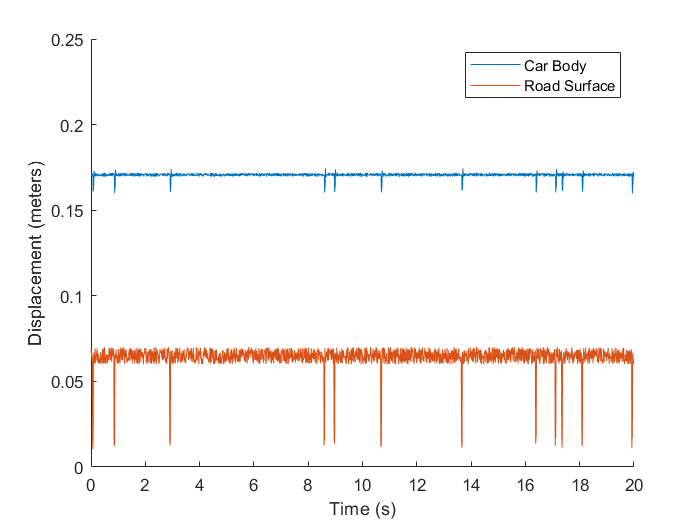

potholes = conv((rand(T/dt,1)>.99),ones(potholeSamp,1),"same")*(-pothole_depth/100);
r = rand(T/dt,1)*(bumpiness/100)+potholes;
%TODO: create more robust terrain generation that can create potholes of
%various sizes and widths, as well as ramps and bumps.


% Run discrete-time simulation
x = x0;
y = zeros(T/dt,1);
N = T/dt;
for i = 1:N
    y(i) = C*x + D*r(i);
    x = A*x + B*r(i);
end


yts = timeseries(y, linspace(0,T,round(T/dt)));
rts = timeseries(r, linspace(0,T,round(T/dt)));

figure("Name","Suspension system filter");
hold on;
plot(yts+.17)
plot(rts+(pothole_depth+1)*.01)
ylim([0,.25])
legend(["Car Body", "Road Surface"])
ylabel("Displacement (meters)")
xlabel("Time (s)")
hold off;

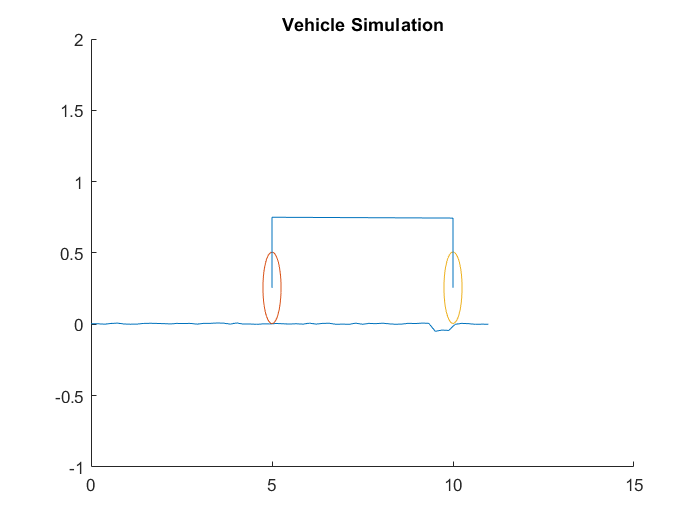



%Draw simulation
for t = round(10/(v*dt)):round(.05/dt):round(T/dt)
    drawFrame(y, r, t, v, dt)
    drawnow
end

Run the simulation and make some observations about the behavior of the car. Does the suspension system mitigate the bumpiness of the road? Does it reduce the impact of potholes? Experiment with different values for the spring constant, damping coefficient, car weight, pothole depth, and so on. Record some thoughts and observations below.

**Answer:**

### Transfer Functions and Eigenvalues

Consider the state space model in the previous section. Find an expression for the transfer function of this model. Create this transfer function in the workspace using the `tf` function in MATLAB and use the `pzmap` function to see the location of poles and zeros.

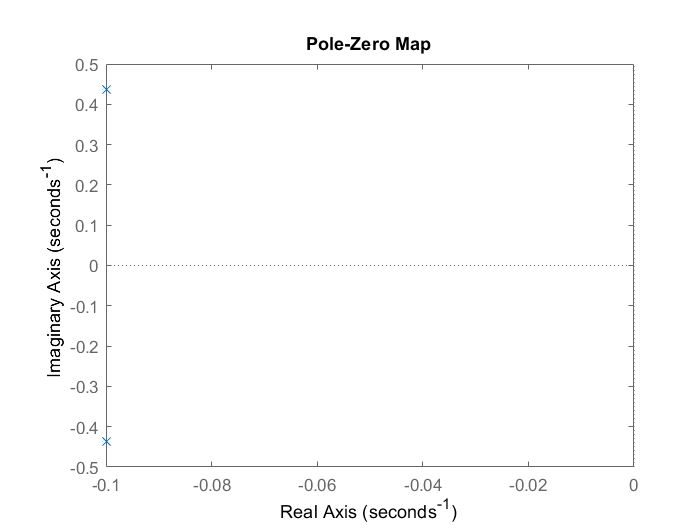

% Temp note: May need to double check this but I believe students should find
% that the system has transfer function k/(ms^2+cs+k)

trans = tf([k],[m c k]);
pzmap(trans)

What do the locations of poles tell you about this system's behavior? What are the mode functions of this system? Record your answer below:

**Answer:**

Change the mass, spring constant, and damping coefficient of the system and examine the effect this has on the transfer function and pole map. Compare this to the effect on the suspension system. What must be true of the poles of the system for it to be critically damped?

**Answer:**

### Case Study

In real life, the mass of a vehicle is not static. Changes in the number of passengers and cargo may affect the response of the suspension system. Consider a heavy-duty pickup truck with a mass of 3000 kg that can hold up to 1000 kg of cargo. Using the simulation below, devise values of `k` and `c` for the truck's suspension systems that work effectively when it is both loaded and unloaded. Assume that the weight is distributed evenly between all 4 wheels.

Test your model using the code from before. Compare the performance of the truck when it is loaded versus when it is unloaded.

% Change these
k = 1

k = 1

c = 1

c = 1


%% TODO: Code to run simulation twice, once for unloaded truck and 
% once for loaded truck


Map the poles and zeros for the loaded and unloaded systems and compare them. What are the mode functions of each system?

## Active Suspension Systems and State Feedback

You may have noticed a problem with the passive suspension system; because the spring constant and damping coefficient of the system remain constant, but the mass of the vehicle can change, it is impossible to ensure the system will always be critically damped. A spring might be too strong for an unloaded vehicle but too weak for a loaded one.

Active suspension systems use sensors and hydraulic actuators to reduce shocks to the vehicle, rather than leaving it to springs. Though they are more complicated systems, they are also more robust and adaptable.

Consider a hydraulic piston that can apply various amounts of force to the vehicle body. When the road is smooth, the piston can remain at a constant length to hold the body in place. When the tires hit a bump, the piston can expand or contract as necessary to minimize the acceleration experienced by the vehicle body.

Image pending: A diagram of the new model and dynamics.

### Open Loop Dynamics

Using the dynamics above, derive the open loop transfer function of the system and plot its pole and zero map.

What do you notice about the location of poles and zeros? Is this system stable? What are its mode functions?

**Answer:**

### Case Study

Devise a controller for the hydraulic piston. The controller receives information about the current length of the piston, the horizontal velocity of the vehicle body, and the horizontal acceleration of the vehicle body. Your mission is to devise a controller for the piston that will take in these three different states and output a force to exert on the vehicle body in order to minimize the acceleration experienced by the passengers.

Express your controller as a function `piston_controller` that takes in three arguments and returns one argument. See the `piston_controller` template in the case study folder. Use the code below to test your controller.

%Testbed

Calculate the transfer function of the closed-loop system and plot the poles and zeros.

Is your system stable? How does it compare to your passive controller at reducing the effect of disturbances on the vehicle body?

**Answer:**

## Extension

Here are some optional problems to further explore control systems.

### Luenburger Observer

We don't always have perfect information about the state of our system. Often we must estimate the state based on the measurements we have available. Suppose that we can measure the length of the piston and the velocity of the vehicle body, but not the acceleration of the vehicle body. Find a way to estimate the complete state of the system from this incomplete information.

%Todo